## Loading in data


subjectNames = {
    'nstdb/118e24';
    'nstdb/118e18';
    'nstdb/118e12';
    'nstdb/118e06';
    'nstdb/118e00';
    'nstdb/118e_6';
    'nstdb/119e24';
    'nstdb/119e18';
    'nstdb/119e12';
    'nstdb/119e06';
    'nstdb/119e00';
    'nstdb/119e_6';
};

% % mitdb/112 doesn't load so don't try it
% subjectNames = {
%     'mitdb/100';
%     'mitdb/101';
%     'mitdb/102';
%     'mitdb/103';
%     'mitdb/104';
%     'mitdb/105';
%     'mitdb/106';
%     'mitdb/107';
%     'mitdb/108';
%     'mitdb/109';
%     'mitdb/111';
%     'mitdb/113';
%     'mitdb/114';
%     'mitdb/115';
%     'mitdb/116';
%     'mitdb/117';
%     'mitdb/118';
%     'mitdb/119';
%     'mitdb/121';
%     'mitdb/122';
%     'mitdb/123';
%     'mitdb/124';
%     'nstdb/118e_6';
%     };
%set number of files
files = length(subjectNames);
%Initialize Arrays
Fs = zeros(files,1);
ecg = cell(files,1);
tm = cell(files,1);
rr = cell(files,1);
rr_tm = cell(files,1);
%loop through all file names
for fi = 1:files
    [ecg{fi,1},Fs(fi),tm{fi,1}]= rdsamp(subjectNames{fi,1},1);
    [rr{fi,1},rr_tm{fi,1}]=ann2rr(subjectNames{fi,1},'atr');
end 
save('nstdb_dataset','ecg','Fs','tm','rr','rr_tm');

## Plotting Data

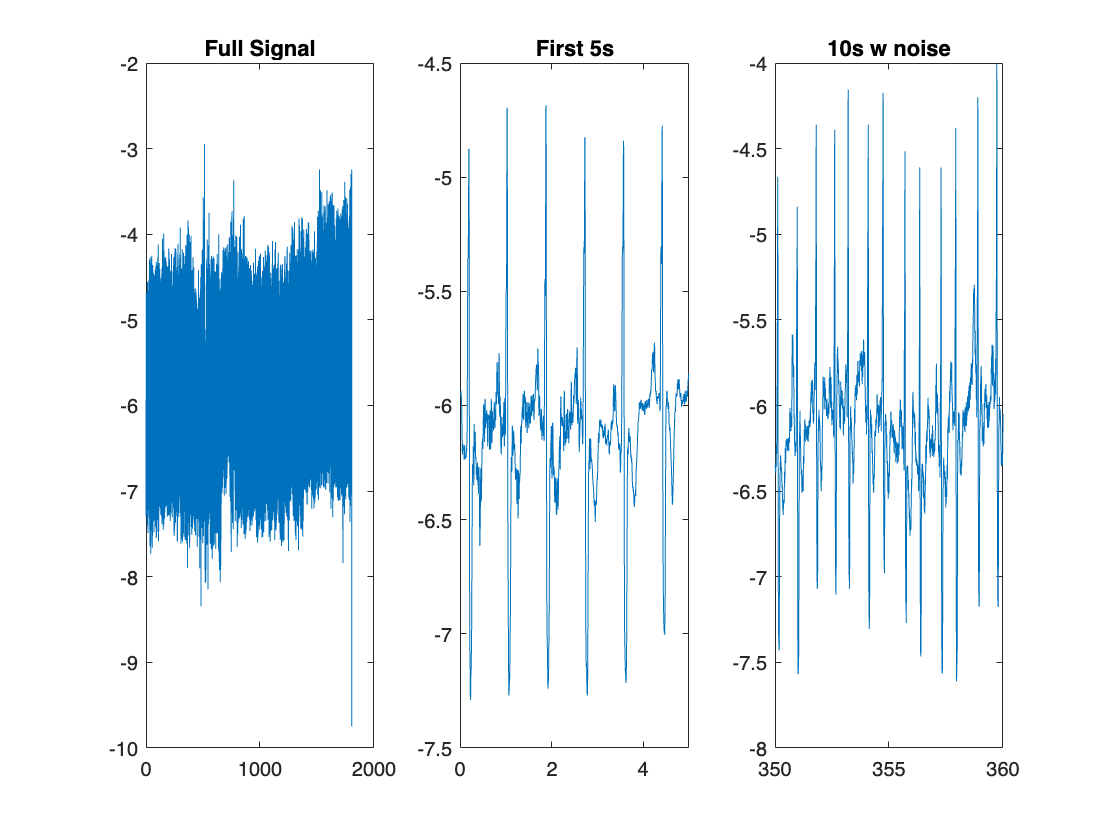

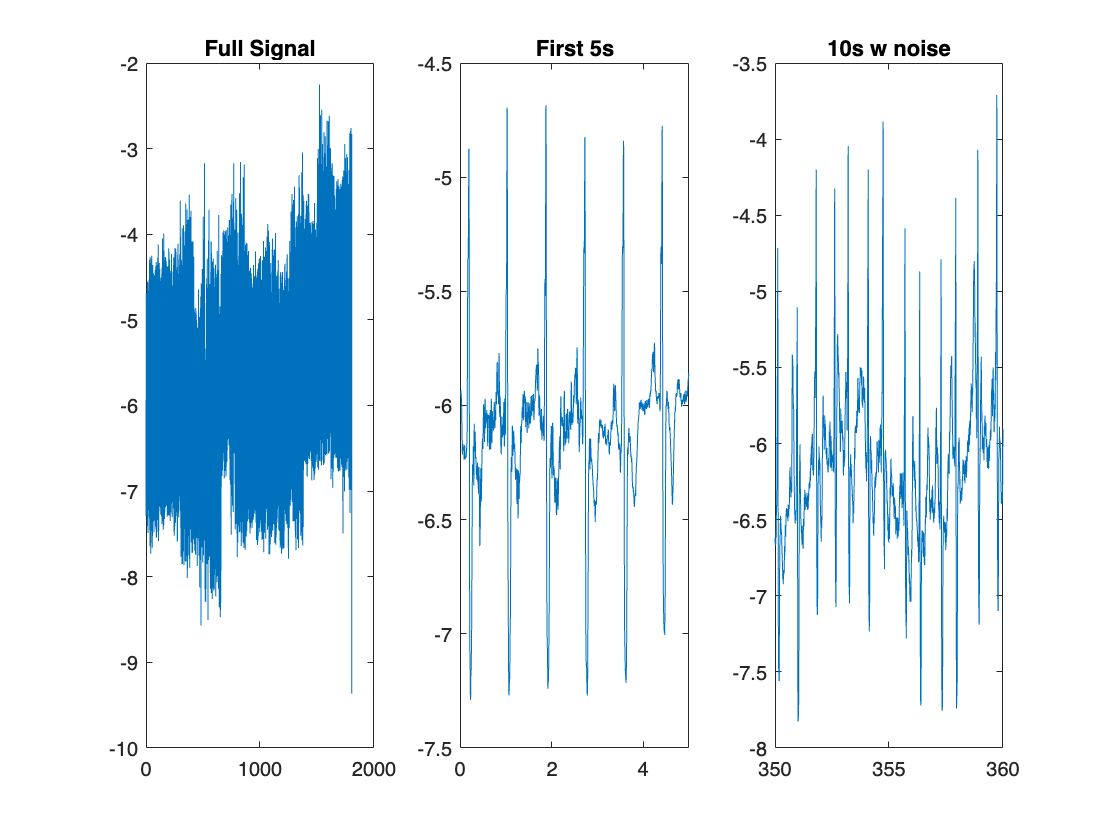

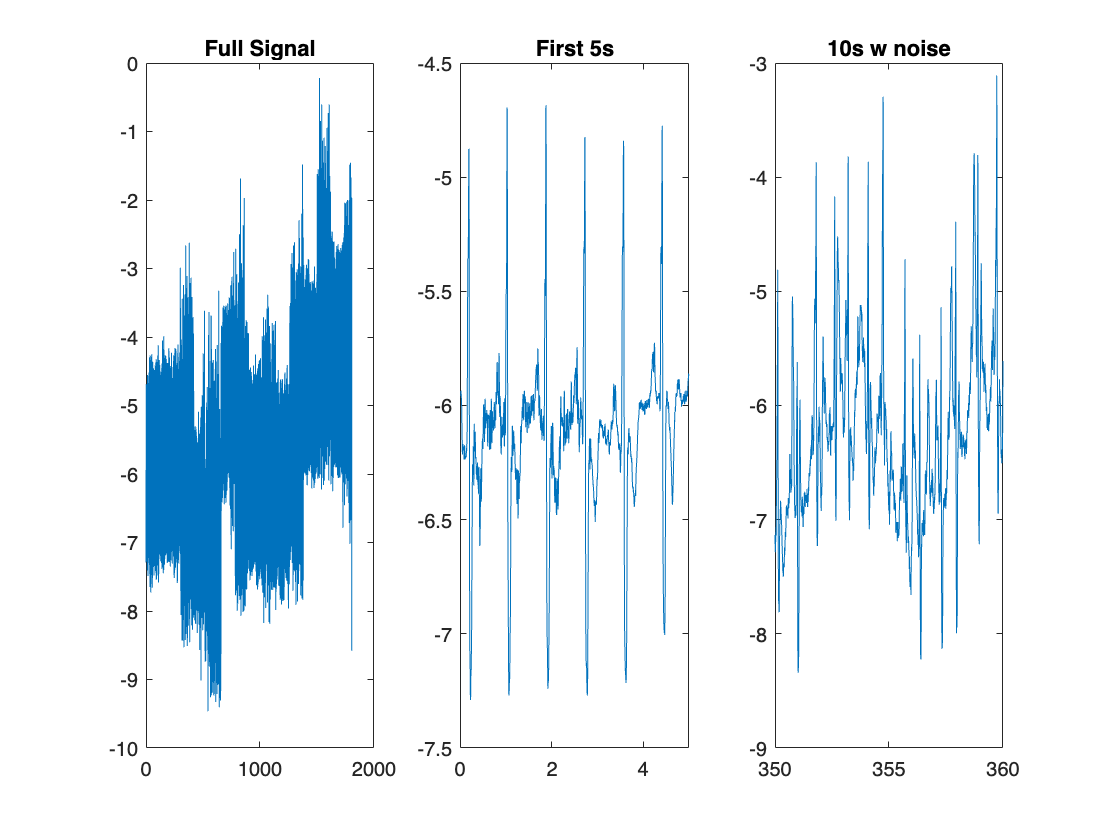

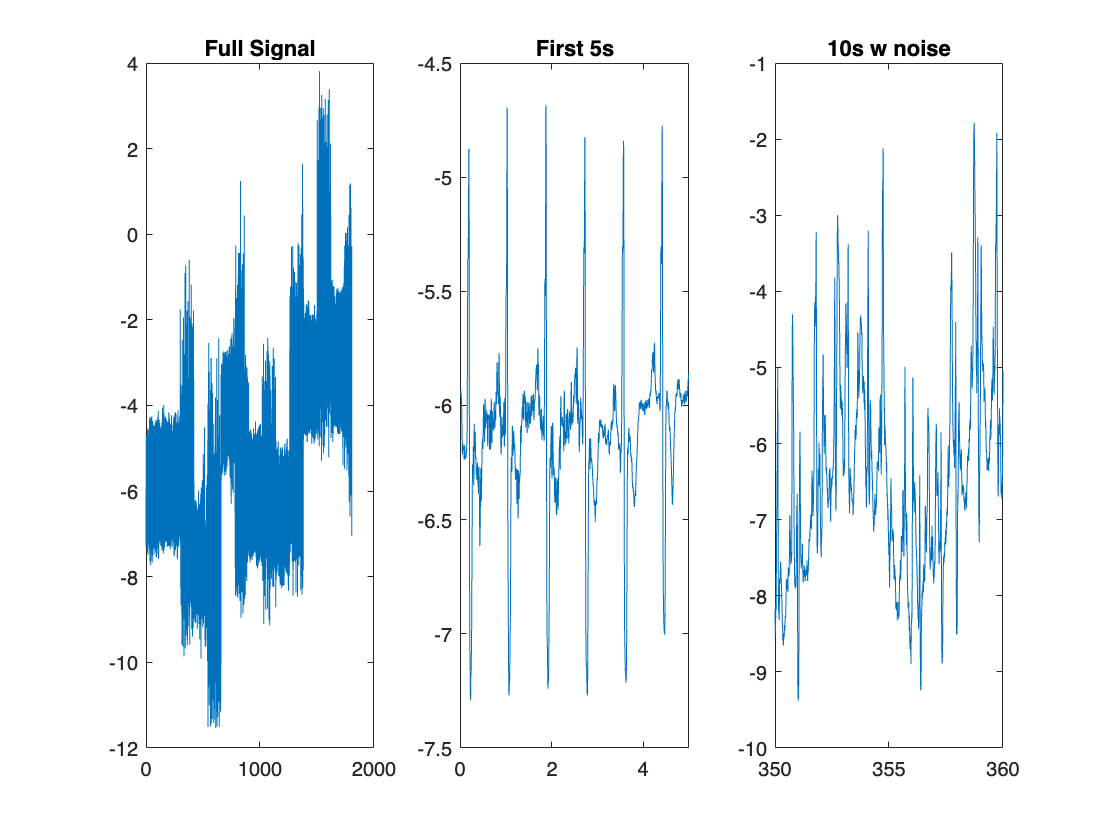

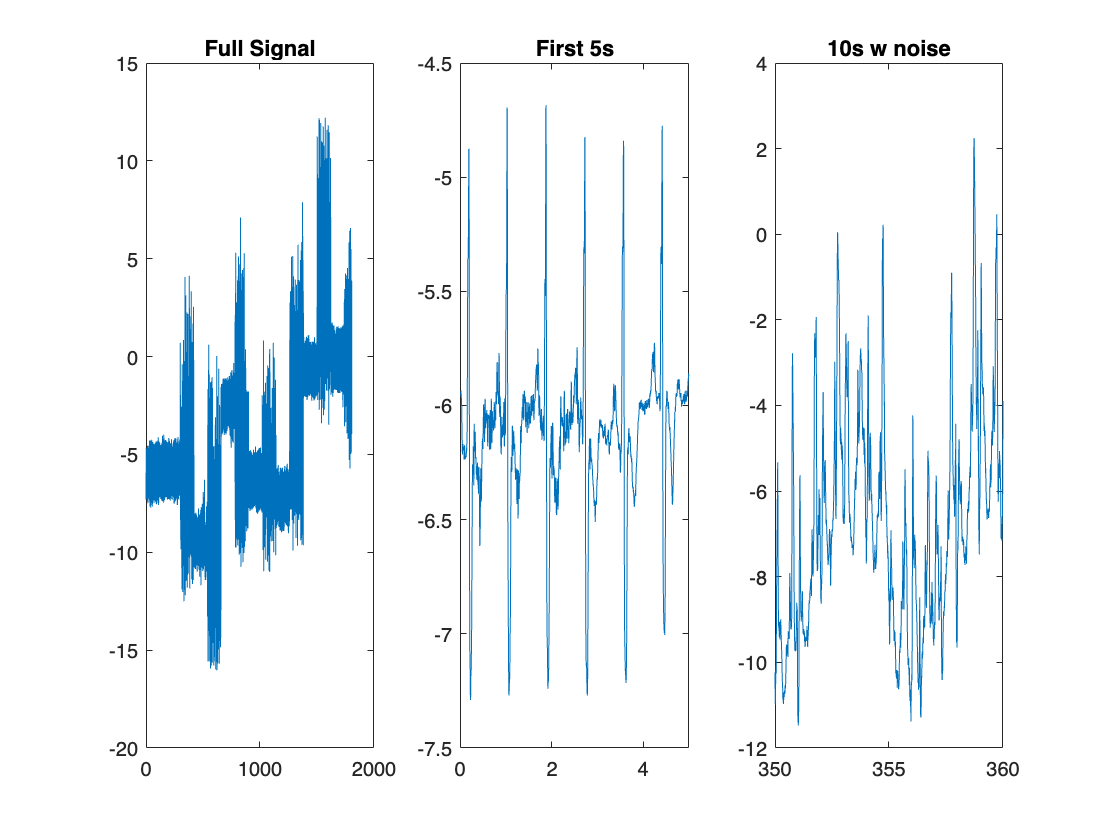

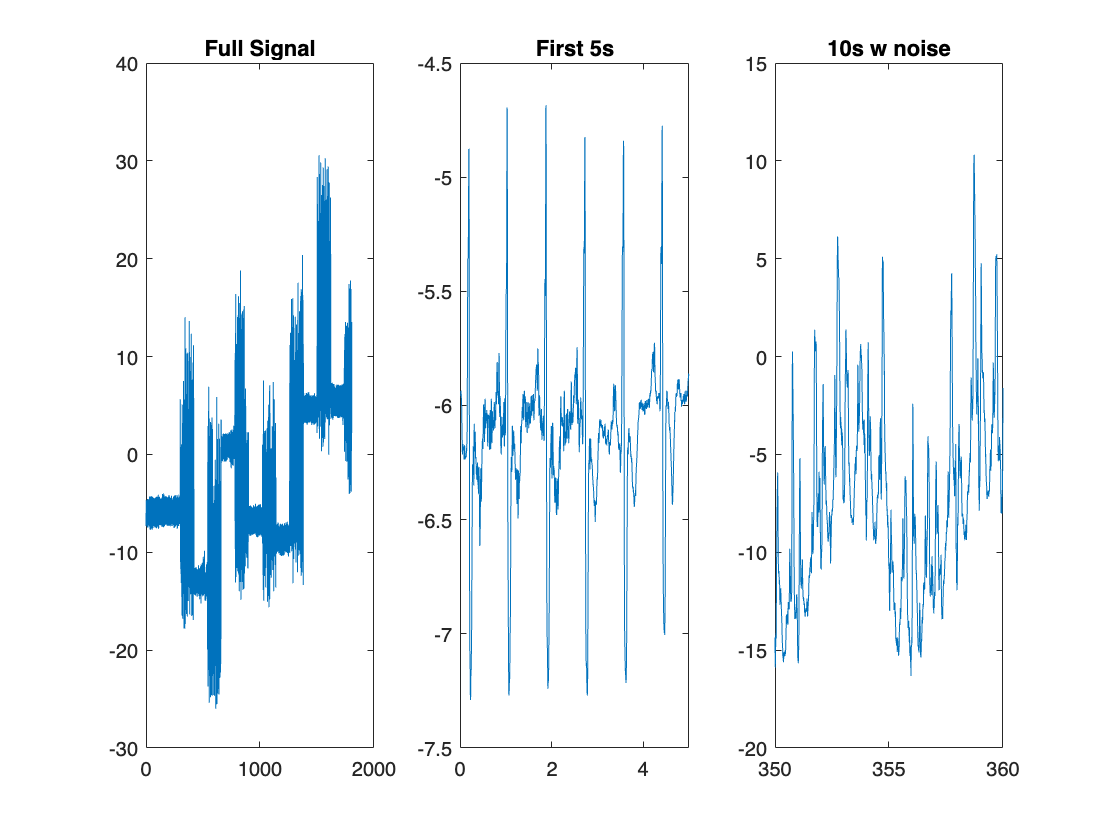

%Example Plot of 118e24
for i = 1:6
    figure; 
    subplot(1,3,1)
    plot(tm{i,1},ecg{i,1})
    title("Full Signal");
    subplot(1,3,2)
    plot(tm{i,1},ecg{i,1})
    xlim([0,5])
    title("First 5s");
    subplot(1,3,3)
    plot(tm{i,1},ecg{i,1})
    xlim([350,360])
    title("10s w noise");
end 

## First Attempt at Wavelet Transform

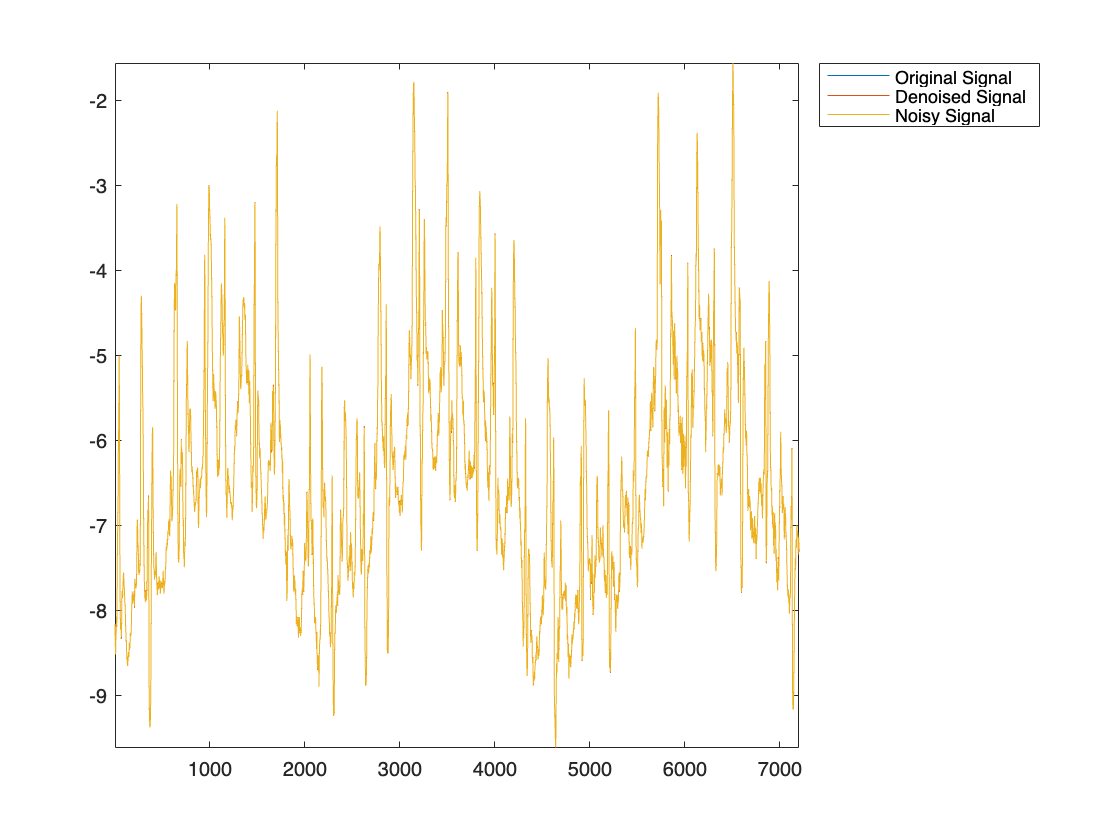

fs = Fs(1);
XN = ecg{4,1}(350*fs:370*fs);
X = ecg{4,1}(350*fs:370*fs);

xd = wdenoise(XN,7);
figure;
plot(X)
hold on;
plot(xd);
hold on; 
plot(XN); 
legend({'Original Signal','Denoised Signal','Noisy Signal'},'Location','NorthEastOutside')
axis tight;
hold off;

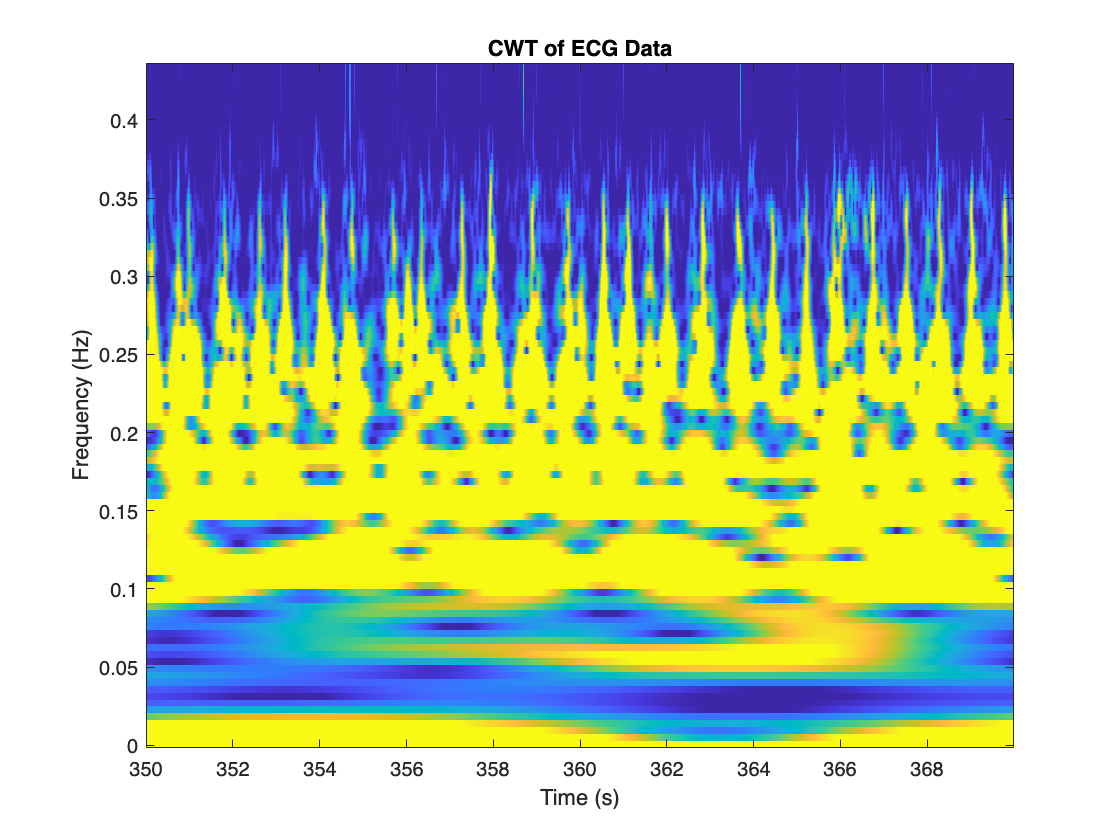

wecg = X;
tim = tm{1,1}(350*fs:370*fs);
fb = cwtfilterbank(SignalLength=length(wecg),Boundary="periodic");
[cfs,f,~,scalcfs] = wt(fb,wecg);
imagesc(tim,f,abs(cfs))
xlabel("Time (s)")
ylabel("Frequency (Hz)")
axis xy
clim([0.025 0.25])
title("CWT of ECG Data")

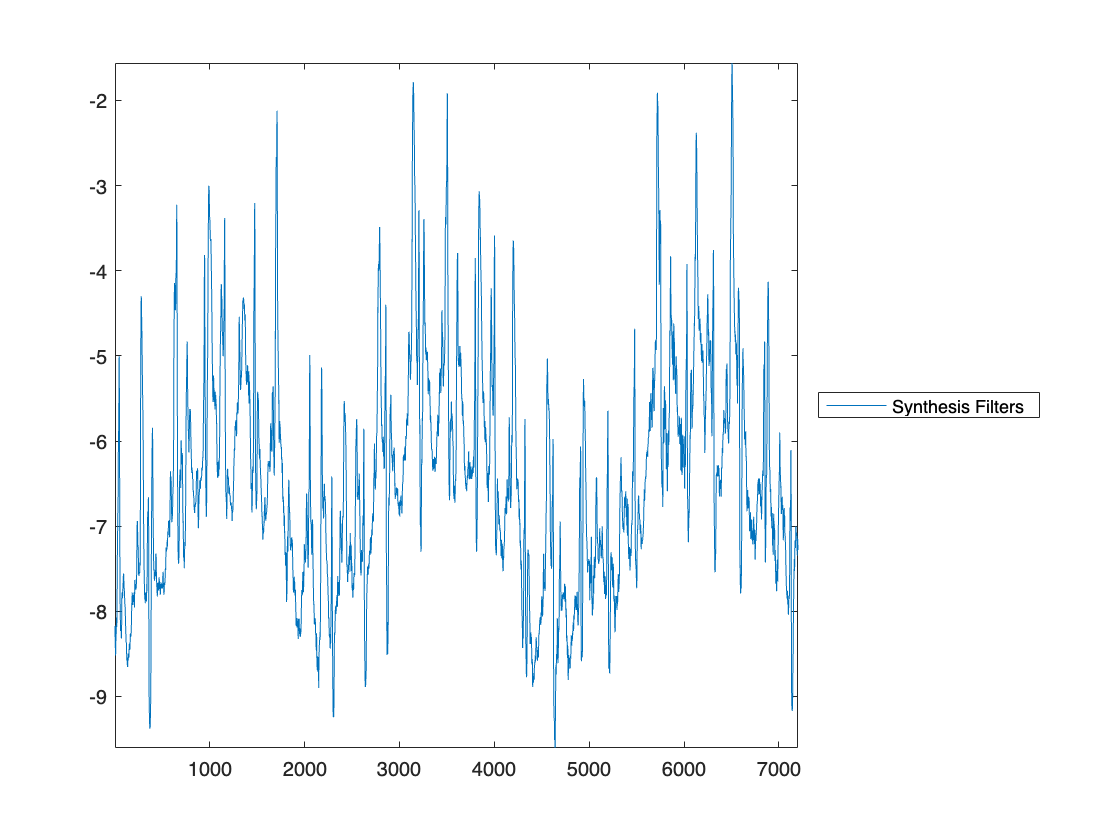

fb = cwtfilterbank(SignalLength=length(wecg),Boundary="periodic");
psif = freqz(fb,FrequencyRange="twosided",IncludeLowpass=true);
xrecAN = icwt(cfs,[],f,[.3, .4],ScalingCoefficients=scalcfs,...
    AnalysisFilterBank=psif);
figure; 
plot([xrecAN' ])
axis tight
    legend("Synthesis Filters","Original",Location="eastoutside")

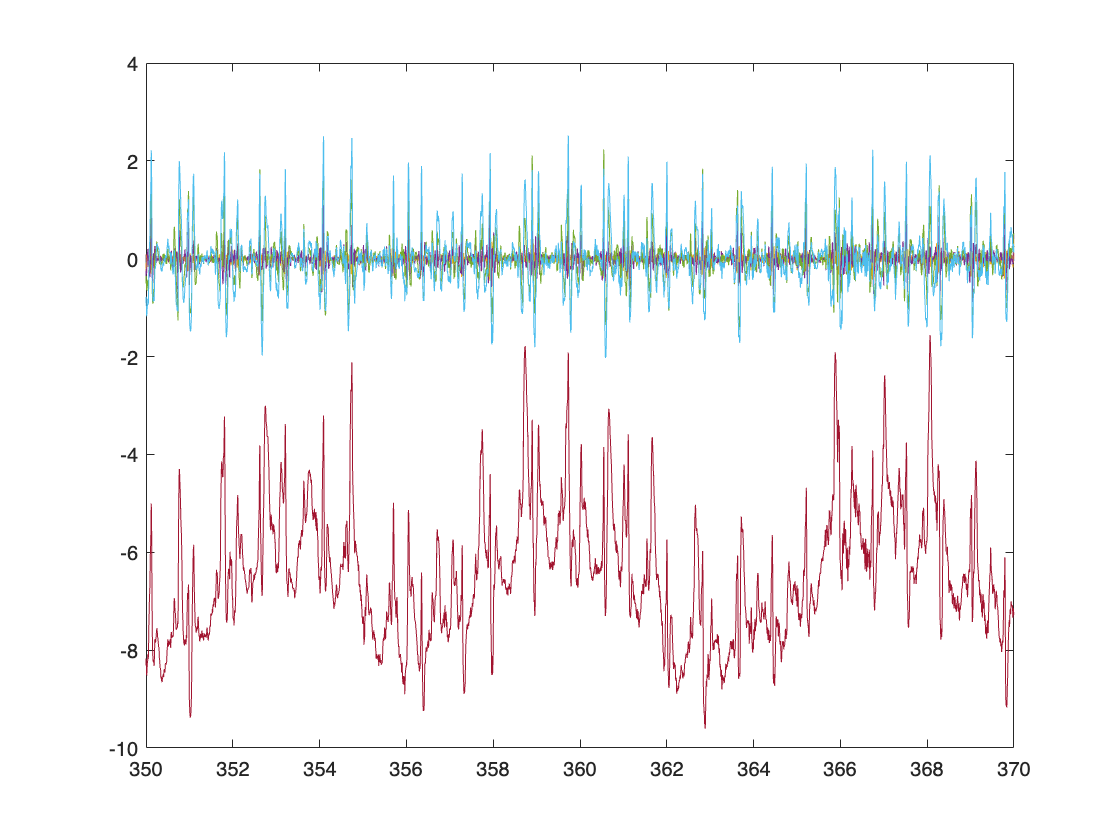

wt = modwt(wecg,7);
wtrec = zeros(size(wt));
y = zeros(length(wt),6);
for i = 1:6
    wtrec(i,:) = wt(i,:);
    y(:,i) = imodwt(wtrec,'sym4');
end 
figure
plot(tim,y)
hold on; 
plot(tim,wecg)

xn = wecg; 
n = length(xn); 
wname = 'sym4'; level = 5; keepap = 1; 
crit = 'shannon'; critv = 0; 
sorh = 's';
dwtmode('per');

                                         
*****************************************
**  DWT Extension Mode: Periodization  **
*****************************************
                                         


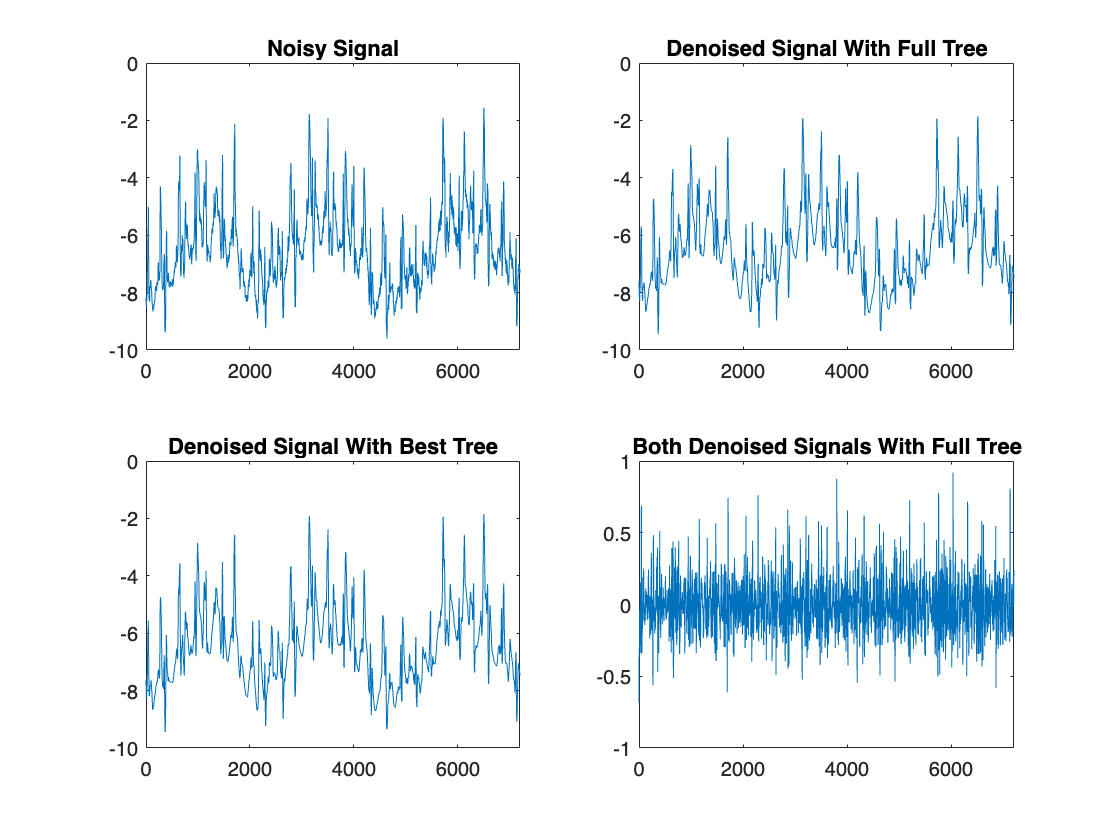

wpt = wpdec(xn,level,wname,crit,critv);
det1 = wpcoef(wpt,2);
sigma = median(abs(det1(:)))/0.06745; 
thr = sigma*sqrt(2*log(length(det1(:))));

[xd, wptree1,f11,f12] = wpdencmp(wpt,sorh,'nobest',thr,keepap);
[xdd,wptree2,f21,f22] = wpdencmp(wpt,sorh,crit,thr,keepap);
figure; 
subplot(2,2,1)
plot(xn); title('Noisy Signal'); xlim([0 n]);
subplot(2,2,2); 
plot(xd); title('Denoised Signal With Full Tree'); xlim([0 n]);
subplot(2,2,3);
plot(xdd); title('Denoised Signal With Best Tree'); xlim([0 n]);
subplot(2,2,4);
plot(xn-xdd); %hold on; plot(xdd)
title('Both Denoised Signals With Full Tree'); xlim([0 n])

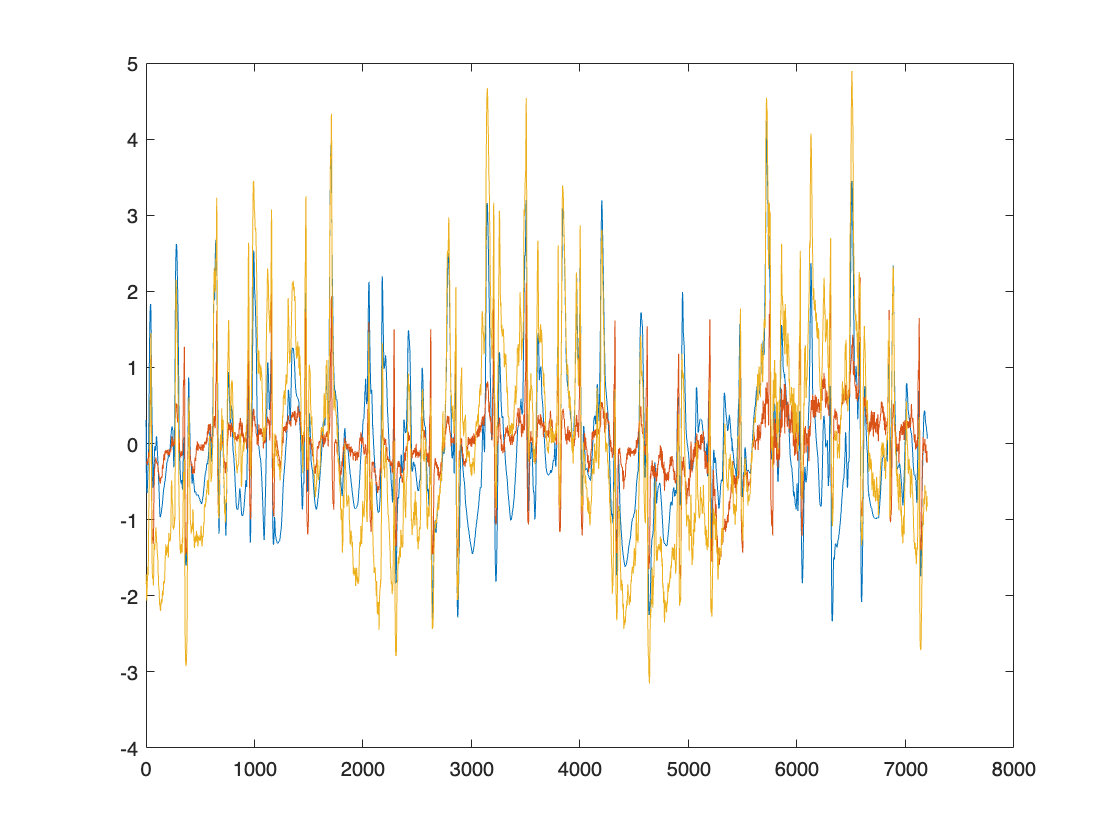

xn1 = wdenoise(xn,4, ...
    Wavelet='sym4', ...
    DenoisingMethod='Bayes', ...
    ThresholdRule='Median', ...
    NoiseEstimate='LevelIndependent');

xn2 = wdenoise(xn,10, ...
    Wavelet='sym4', ...
    DenoisingMethod='Bayes', ...
    ThresholdRule='Median', ...
    NoiseEstimate='LevelIndependent');

xn3 = wdenoise(xn,10, ...
    Wavelet='sym4', ...
    DenoisingMethod='UniversalThreshold', ...
    ThresholdRule='Soft', ...
    NoiseEstimate='LevelDependent');


signal = xdd - xn3; 

figure; 
plot(signal); 
orig = ecg{1,1}(350*fs:370*fs);
morig = orig - mean(orig);
hold on;
plot(morig);
hold on;
mxn = xn - mean(xn);
plot(mxn);

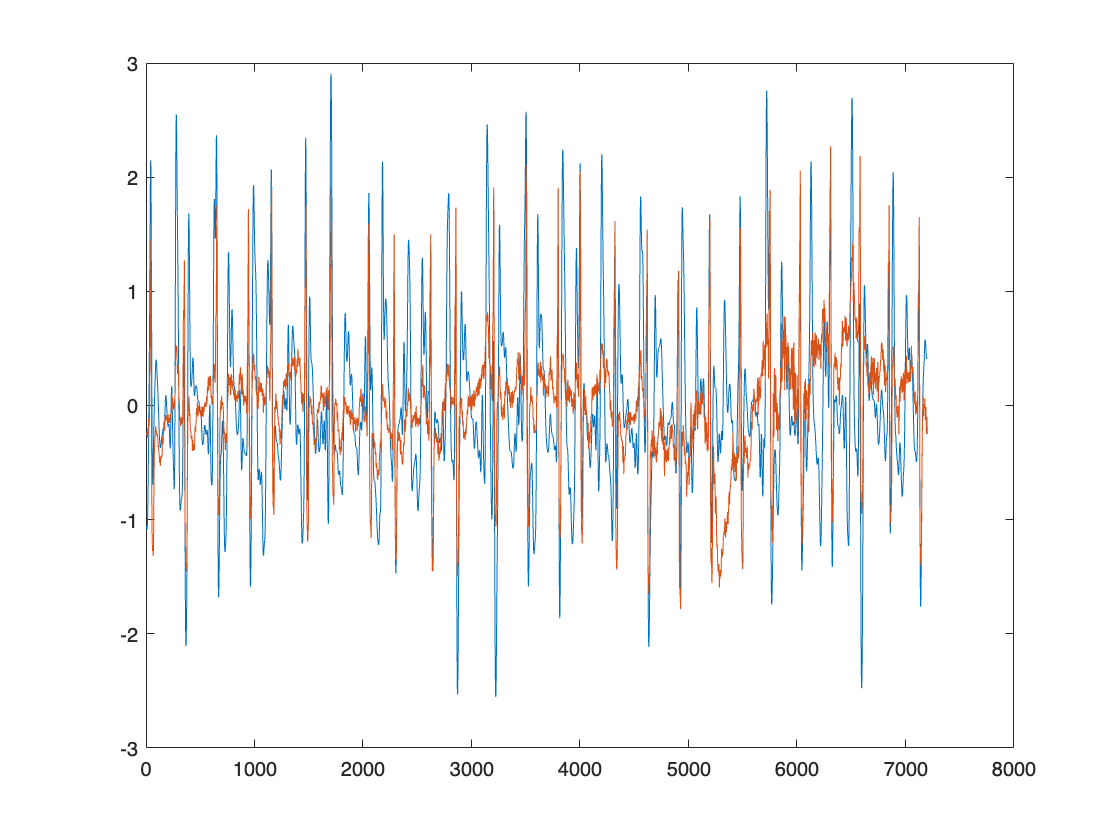


%Parameters
sampleRate = 1;
wavelet = 'amor';

%Compute time vector
t = 0:1/sampleRate:(length(xn)*1/sampleRate)-1/sampleRate;

%Compute CWT
%If necessary, substitute workspace variable name for xn as first input to cwt() function in code below
%Run the function call below without output arguments to plot the results
[waveletTransform,frequency] = cwt(xn, wavelet);
%scalogram = abs(waveletTransform);
xrec = icwt(waveletTransform,wavelet,frequency,[.005 0.05]);
figure; 
plot(xrec);
hold on; 
plot(morig);

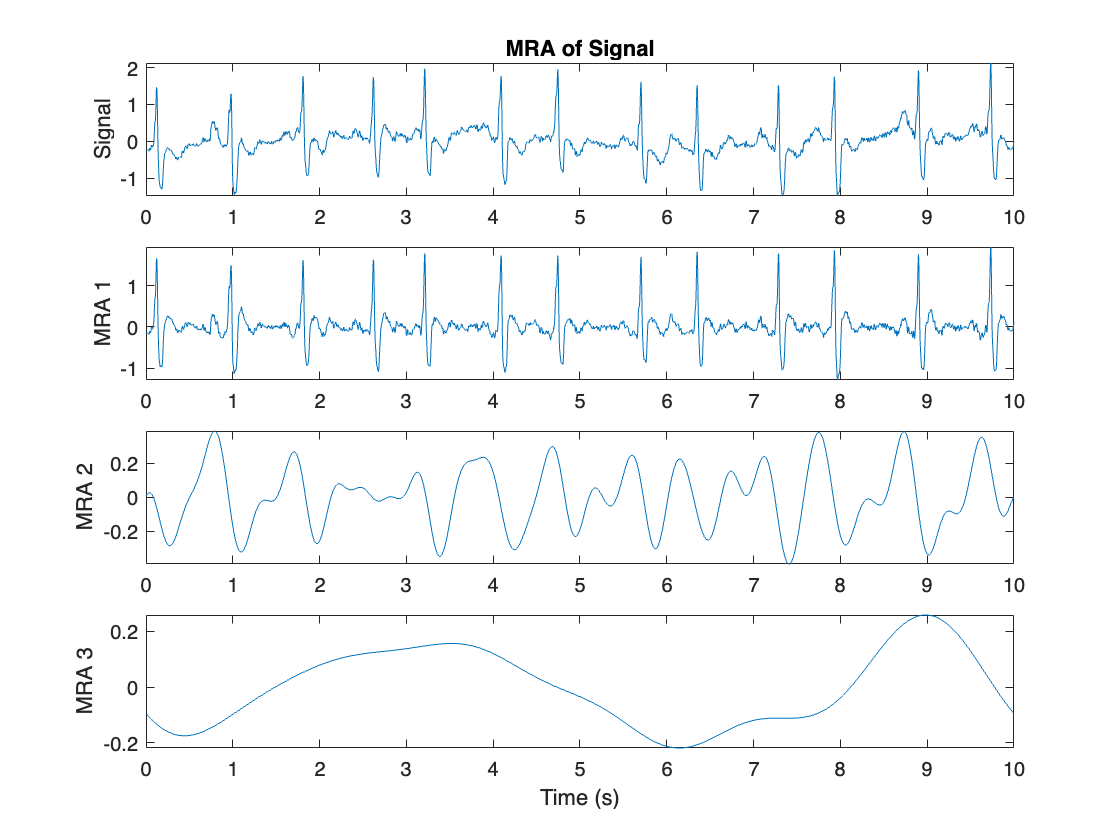

wf = ecg{1,1}(350*fs:360*fs);
mwf = wf - mean(wf);
sig = mwf; 
mp = 3;
[mra,cfs] = ewt(sig,'MaxNumPeaks',mp,"LogSpectrum",true);
fs = Fs(1);
figure; 
subplot(mp+1,1,1)
t = (0:length(sig)-1)/fs;
plot(t,sig)
title('MRA of Signal')
ylabel('Signal')
axis tight
for k=1:size(mra,2)
    subplot(mp+1,1,k+1)
    plot(t,mra(:,k))
    ylabel(['MRA ',num2str(k)])
    axis tight
end
xlabel('Time (s)')

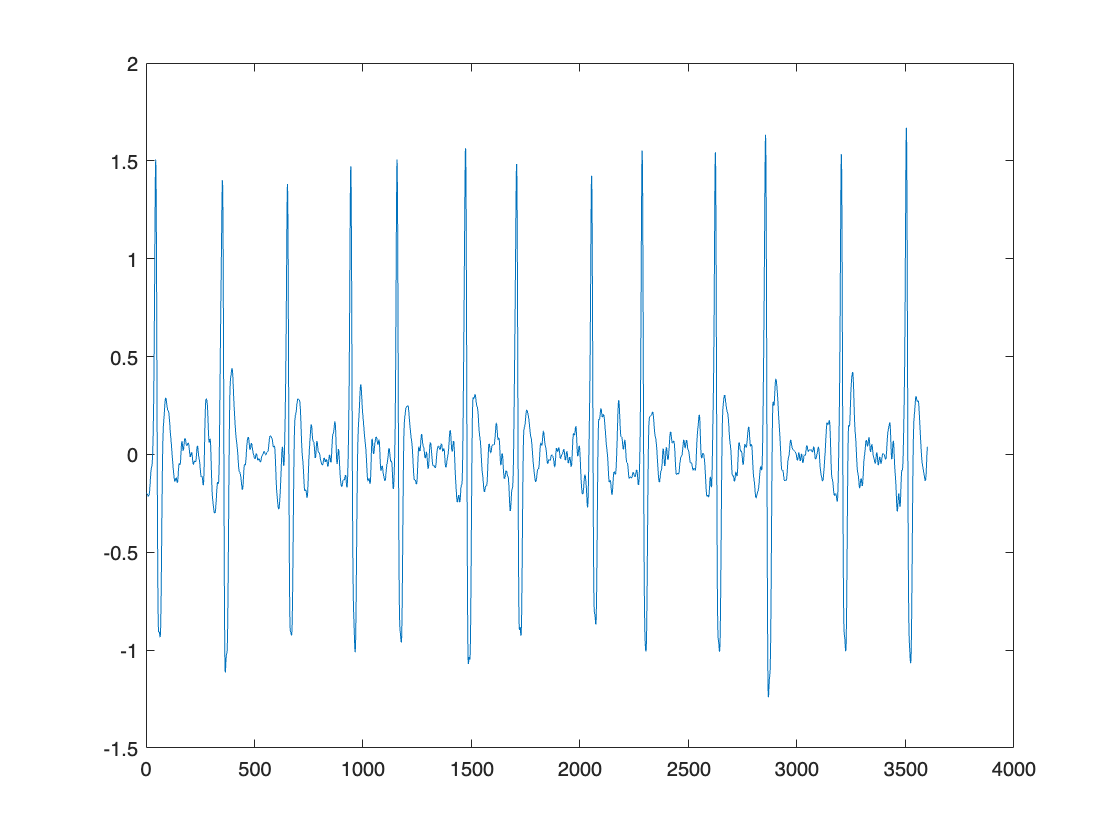

figure; 
[waveletTransform,frequency] = cwt(mra(:,1), wavelet);
%scalogram = abs(waveletTransform);
xrec = icwt(waveletTransform,wavelet,frequency,[.01 0.08]);
figure; 
plot(xrec);

% hold on; 
% plot(mra(:,1));

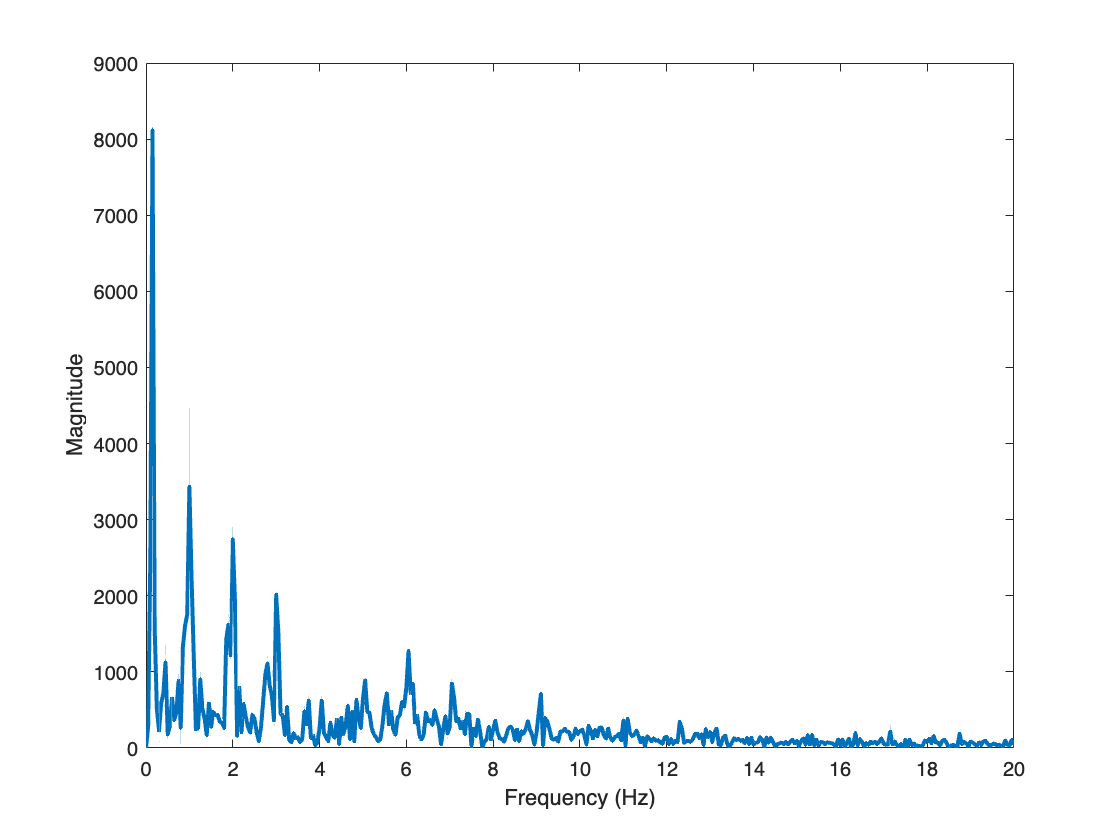

wf = ecg{5,1}(350*fs:370*fs);
mwf = wf - mean(wf);
Y = fft(mwf);
L = length(mwf);
figure; 
plot(fs/L*(0:L-1),abs(Y),"LineWidth",2)
xlim([0,20])
xlabel('Frequency (Hz)')
ylabel('Magnitude')

% Preprocessing (if needed)

Fs = fs; % Sampling frequency
t = (0:length(mwf)-1)/fs;
ecg_signal = mwf; % Signal with two components

filtered_ecg_signal = bandpass(ecg_signal, [1, 20], Fs); % Replace Fs with your sampling frequency
filtered_ecg_signal = filtered_ecg_signal(Fs*1:end);

PatchHW=50;  % patch half-width; ~ size of smallest feature, in samples
P = 2000;  
lambda = 0.6*std(filtered_ecg_signal)/3;

[filtered_ecg_signal,debug] = NLM_1dDarbon(filtered_ecg_signal,lambda,P,PatchHW);
mp = 4;
[mra,cfs] = ewt(denoisedSig(~isnan(denoisedSig)),'MaxNumPeaks',mp,"LogSpectrum",true);

Unrecognized function or variable 'denoisedSig'.

fs = Fs(1);
figure; 
subplot(mp+1,1,1)
t = (0:length(filtered_ecg_signal)-1)/fs;
plot(t,filtered_ecg_signal)
title('MRA of Signal')
ylabel('Signal')
axis tight
t = (0:length(mra(:,k))-1)/fs;
for k=1:size(mra,2)
    subplot(mp+1,1,k+1)
    plot(t,mra(:,k))
    ylabel(['MRA ',num2str(k)])
    axis tight
end
xlabel('Time (s)')
% Perform wavelet denoising
level = 2; % Decomposition level
wname = 'db4'; % Wavelet name
filtered_ecg_signal = mra(:,1);
denoised_ecg_signal = wdenoise(filtered_ecg_signal,6, ...
    Wavelet='sym4', ...
    DenoisingMethod='Bayes', ...
    ThresholdRule='Mean', ...
    NoiseEstimate='LevelDependent');

% Visualize original and denoised signals
t = (1:length(filtered_ecg_signal)) / Fs; % Time vector
figure; 
subplot(2,1,1)
plot(t, filtered_ecg_signal);
ylim([-2, 2])
subplot(2,1,2)
plot(t, denoised_ecg_signal);
ylim([-2, 2])


